# A simple Application of the Kalman Predictor

## Tracking of a Moving Object

Let us study the motion of an object moving along a straight line, as schematised in the following figure

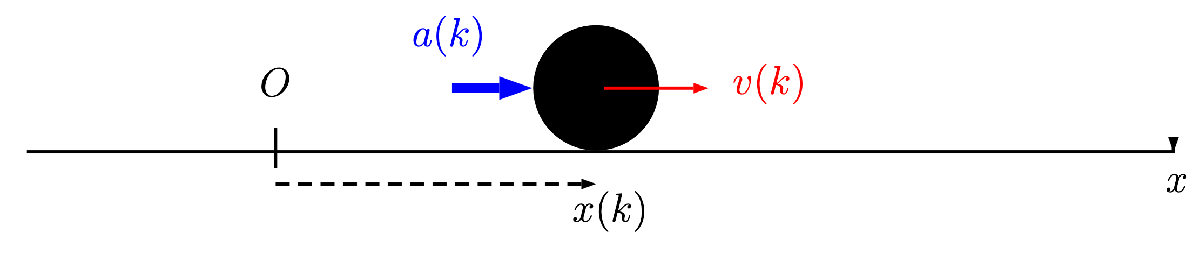

The following assumptions hold:

- the moving object has negligible dimensions, so that it can be described as a **point material**, using only kinematics equations

- position and speed of the object are observed, both affected by measurement noise

$\left\{ \begin{array}{rcl}
y_1(k) &=& x(k) + \eta_1(k) \\
y_2(k) &=& v(k) + \eta_2(k) 
\end{array}
\right. \qquad \eta_1(\cdot) \sim \mathrm{WNG}(0,\,1/100) \,,\; \eta_2(\cdot) \sim \mathrm{WNG}(0,\,4) $    (1)

- at each sampling instant $k\,\Delta$ [with **sampling period** $\Delta = 0.01\;\mathrm{s}$], acceleration $a(k)$ is applied to the system 

It is requested to

-  describe the system with a model in state equations, with the state variables of the system described by position [ $x_1(k) = x(k)$] and speed of the material point [ $x_2(k) = v(k)$ ], taking into account the measurement noise in equations (1). 

- simulate the motion of the object (taking into account the measurement noise) in the time interval $t_k = k\cdot \Delta ,\; k=0,\,1,\,\ldots 200$

- determine the recursive **Kalman predictor** that provides the optimal prediction of the state $\hat{x}(k + 1 | k)$ for the system.

- compare the performance of the recursive Kalman predictor with the one of the **steady-state Kalman predictor**.

Let us assume that the process noise is given by $\epsilon(k) = [\epsilon_1(k)\; \epsilon_2(k) ]^{\top} $ , where $\epsilon_{i}(k) \sim \mathrm{WNG}(0,\,1/1000) \quad i=1,\,2$ and $\epsilon_1$, $\epsilon_2$ independent r.v.  

 Moreover, the acceleration $a(k)$ acting on the system is identically zero.

Finally, assume that the initial state of the system is $[\hat{x}_1(1),\;\hat{x}_2(1)]^{\top} = [0,\;-0.5]^{\top}$ and the corresponding uncertainty matrix is $P_1 = 10 \cdot I_2$ ( $I_2$ is an identity matrix of order $2$), whereas the effective initial state is $[x_1(1),\;x_2(1)]^{\top} = [-0.43\; 0.5979]^{\top}$

## Solution

clear
close all
clc

Delta = 0.01; % sampling period [s]

### The model - Kinematics of moving objects 1D

Assuming zero acceleration, the material point moves with constant speed. The state equations describing the object movement are as follows 


$$\left\{ \begin{array}{rcl}
x(k+1) &=& x(k) + \Delta \cdot v(k) \\
v(k+1) &=& v(k) + \Delta \cdot a(k) = v(k) \\
y_1(k) &=& x(k) \\
y_2(k) &=& v(k)
\end{array} \right. \qquad \Longrightarrow \qquad 
\left\{ \begin{array}{rcl}
x_1(k+1) &=& x_1(k) + \Delta \cdot x_2(k) \\
x_2(k+1) &=& x_2(k) \\
y_1(k)&=& x_1(k)\\
y_2(k) &=& x_2(k)
\end{array} \right.$$


The model needed by the Kalman predictor, taking into account also the process and measurement noises, becomes


$$\left\{ \begin{array}{rcl}
x_1(k+1) &=& x_1(k) + \Delta \cdot x_2(k) +\epsilon_1(k) \\
x_2(k+1) &=& x_2(k) +\epsilon_2(k) \\
y_1(k) &=& x_1(k) +\eta_1(k)\\
y_2(k) &=& x_2(k) +\eta_2(k)
\end{array} \right. \qquad \Longrightarrow \qquad 
\left\{
\begin{array}{l}
\left[ \begin{array}{c} x_1(k+1) \\x_2(k+1) \end{array} \right] = 
\left[ \begin{array}{cc}
1 & \Delta \\
0 & 1 \end{array} \right] \cdot \left[ \begin{array}{c} x_1(k) \\x_2(k) \end{array} \right] + 
 \left[ \begin{array}{c} \epsilon_1(k) \\ \epsilon_2(k) \end{array} \right]   \\
\\
\left[ \begin{array}{c} y_1(k) \\ y_2(k) \end{array} \right] = 
\left[ \begin{array}{cc}
1 & 0 \\ 0 & 1
\end{array} \right]  \cdot \left[ \begin{array}{c} x_1(k) \\x_2(k) \end{array} \right] + 
 \left[ \begin{array}{c} \eta_1(k) \\ \eta_2(k) \end{array} \right]
\end{array}
\right.$$


with


$$V_1 = \mathrm{var} \left[\begin{array}{c}
\epsilon_1(k) \\
\epsilon_2(k)
\end{array} \right] = 
 \left[\begin{array}{cc}
2 & 0 \\
0 & 2
\end{array} \right] \qquad 
V_2 = \mathrm{var} \left[\begin{array}{c}
\eta_1(k) \\
\eta_2(k)
\end{array} \right] = 
 \left[\begin{array}{cc}
1 & 0 \\
0 & 10
\end{array} \right] 
$$


#### Initialization

proc_noiseSTD = sqrt(2); %sqrt(0.001); % the process noise standard deviation
meas_noiseSTD_1 = 1; %.1;
meas_noiseSTD_2 = sqrt(10); %2; % the measurement noise standard deviation

V1 = [proc_noiseSTD.^2 , 0 ;...
          0, proc_noiseSTD.^2]; % the process noise variance matrix
V2 = diag([meas_noiseSTD_1.^2 ; meas_noiseSTD_2.^2]); % the measurement noise variance matrix

% bisogna stare attenti a costruire la matrice diagonale se ho due varianze
% e due variabili

hat_x1 = [0;-0.5]; % initial state
P_1 = 10*eye(2); % initial state variance

time_steps = Delta .* (0:200);

meas_noise = diag([meas_noiseSTD_1, meas_noiseSTD_2]) * randn(2,numel(time_steps));
proc_noise = diag([proc_noiseSTD, proc_noiseSTD]) * randn(2,numel(time_steps));

#### The Moving Object


X = zeros(2, numel(time_steps));
Y = zeros(2, numel(time_steps));

% ------------------------------
% system model equations
%
% x(k+1) = A x(k) 
%   y(k) = C x(k) + v2(k) 
%
%  v2(k) <--> measurement noise
%
% state vector x(k)
% 
% x(k) = [x1(k) x2(k)]'
%

A = [1 Delta; 0 1];
C = eye(2);

x_init = [-0.43;.5979]; % initial state <-- NB different from the initial guess!!
X(:,1) = x_init;
Y(:,1 ) = meas_noise(:,1);


% -- simulation of the moving object ---
for k=1:numel(time_steps)-1
    Y(:,k) = C * X(:,k) + meas_noise(:,k);
    X(:, k+1) = A * X(:,k); % no process noise <-- no uncertainty in the model!!
    % non ho incertezza qua sopra, perche` il modello fisico vero non ha
    % incertezza. Sono in un caso teorico, se fossi in un sistema reale
    % dovrei anche mettere il rumore qua
end % for k
Y(:,numel(time_steps)) = C * X(:,numel(time_steps)) + meas_noise(:,numel(time_steps));

#### The Kalman Predictor

Given the system dynamics described by


$$\left\{ \begin{array}{rcl}
	x(t+1) &=& F x(t) + v_1(t) \\
	y(t) &=& H x(t) + v_2(t) \qquad x, \, v_1 \in \mathbb{R}^n, \, y, \, v_2 \in \mathbb{R}^p
	\end{array} \right.$$


the Kalman filter acting as one-step ahead predictor is


$$\left\{
\begin{array}{rcl}
\hat x(t+1 \, \vert \, t) &=&
			F \, \hat x (t\, \vert \,t-1)
			+ K(t) \cdot \big(y(t)-H\,\hat x (t\, \vert \,t-1)\big)  \\
K(t) &=& F \cdot P(t) \cdot H^{\top}
			\left [
			H \cdot P(t) \cdot H^{\top} + V_2
			\right ]^{-1} \\ 
P(t+1) &=& F \, \left \{
			P(t) - P(t) H^{\top} \,
			\left [
			V_2 + H P(t) H^{\top}
			\right ]^{-1} \, H P(t)
			\right \} \, F^{\top} + V_1
\end{array}
\right.$$


F = A; 
H = C; 
Nx = size(F,1);


N = numel(time_steps);

xhat = zeros(Nx,N); % output of the Kalman 1-step ahead predictor
xhat(:,1) = hat_x1; % 1st state a priori estimation

y = Y; % the measurements
e = zeros(size(y)); % innovation 

P = zeros(Nx,Nx,N);
P(:,:,1) = P_1; % 1st P matrix

% ------ evaluating the state prediction ---------
for k = 1:(N-1)
    
    e(:,k) = y(:,k) - H*xhat(:,k); % calcolo innovazione
    cP = P(:,:,k); 
    K = (F*cP*H')/(H*cP*H'+V2); % pag 43
    xhat(:,k+1) = F*xhat(:,k) + K*e(:,k);
    Pnew = V1+F*(cP-(cP*H'/(V2+H*cP*H'))*H*cP)*F'; % pag 48
    if (k<N)
        P(:,:,k+1) = Pnew;
    end
    
end % for k 

#### State Prediction vs State

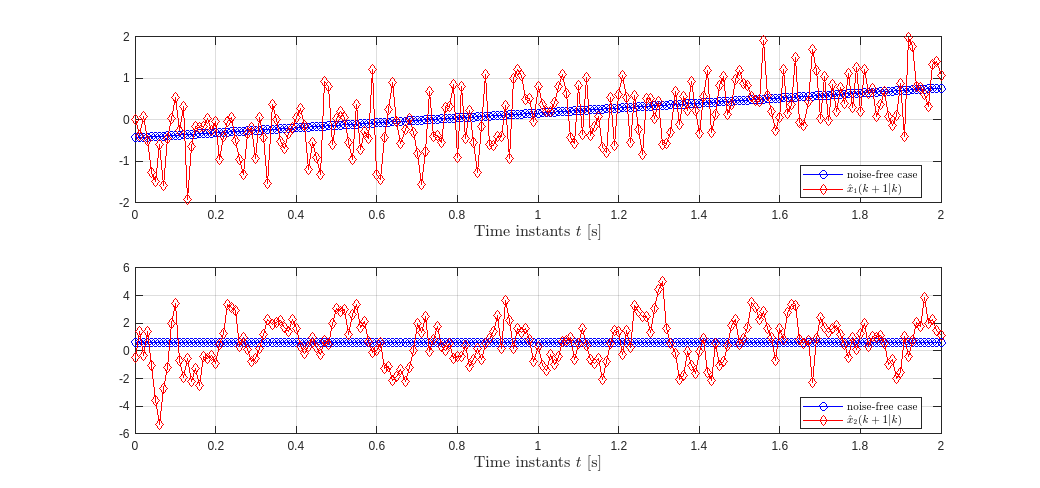

figure('Units','normalized','Position',[0.1, 0.1, 0.9, 0.75]);
hp1 =subplot(2,1,1);
plot(time_steps, X(1,:),'bo-'); hold on
plot(time_steps,  xhat(1,:),'rd-')
grid on; zoom on;xlim([min(time_steps), max(time_steps)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
legend('noise-free case', '$\hat{x}_{1}(k+1 | k)$', 'Interpreter', 'latex',...
         'Location', 'best');

hp2= subplot(2,1,2);
plot(time_steps, X(2,:),'bo-'); hold on
plot(time_steps,  xhat(2,:),'rd-');
grid on; zoom on;xlim([min(time_steps), max(time_steps)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
legend('noise-free case', '$\hat{x}_{2}(k+1 | k)$', 'Interpreter', 'latex',...
         'Location', 'best');

Note the convergence of the predictions to the state variables, despite the "wrong" initial guess.

### The Steady-State Kalman Predictor

What happens to the filter gain $K(t)$ and to the state covariance matrix $P(t)$ when $t \to \infty$?

NN = 500; % try using N = 500 or 50000. What happens to the final matrix P? 
PP = zeros(Nx,Nx,NN);
PP(:,:,1) = P_1; % 1st P matrix

% ------ evaluating the state prediction ---------
for k = 1:(NN-1)
    
    
    cP = PP(:,:,k);
    KK = (F*cP*H')/(H*cP*H'+V2);
    
    Pnew = V1+F*(cP-(cP*H'/(V2+H*cP*H'))*H*cP)*F';
    if (k<NN)
        PP(:,:,k+1) = Pnew;
    end
    
end % for k 
PP(:,:,1)

ans =     10     0
     0    10


PP(:,:,NN)

ans =     2.7326    0.0433
    0.0433    5.5822


KK

KK =     0.7322    0.0043
    0.0074    0.3582


#### Solving the Algebraic Riccati Equation

[Pbar, Kbar]= idare(F, H, V1, V2)

Pbar =     2.7321    0.0088
    0.0088    5.5827


Kbar =     0.7321    0.0088
    0.0002    0.3583


So the steady-state predictor is

xxhat = zeros(Nx,N); % output of the Kalman 1-step ahead predictor
xxhat(:,1) = hat_x1; % 1st state a priori estimation

y = Y; % the measurements
e = zeros(size(y)); % innovation 

Pinf = Pbar;

% ------ evaluating the state prediction ---------
for k = 1:(N-1)
    
    e(:,k) = y(:,k) - H*xxhat(:,k);
    
    
    xxhat(:,k+1) = F*xxhat(:,k) + Kbar*e(:,k);
    
    
end % for k 



### Comparison of the Results

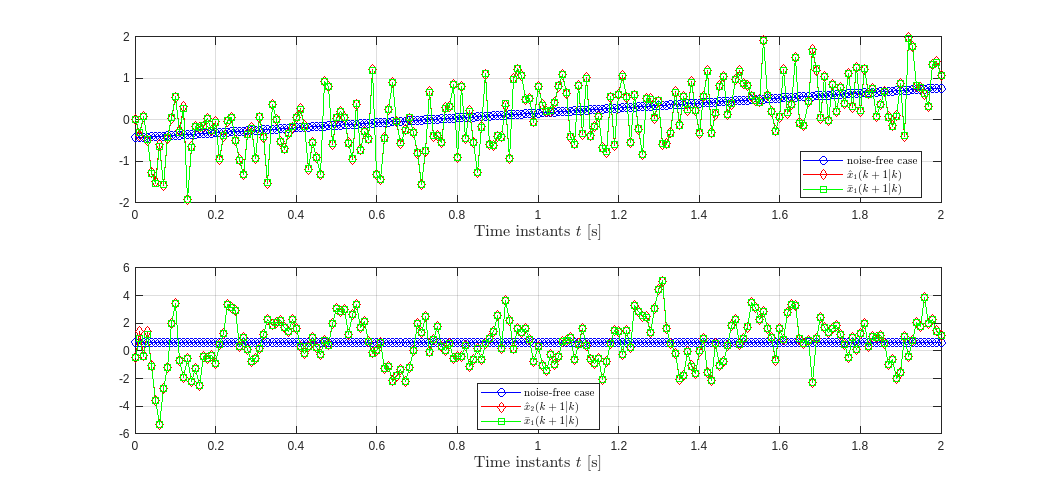

figure('Units','normalized','Position',[0.1, 0.1, 0.9, 0.75]);
hp1 =subplot(2,1,1);
plot(time_steps, X(1,:),'bo-'); hold on
plot(time_steps,  xhat(1,:),'rd-');
plot(time_steps,  xxhat(1,:),'gs-');
grid on; zoom on;xlim([min(time_steps), max(time_steps)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
legend('noise-free case', '$\hat{x}_{1}(k+1 | k)$', '$\bar{x}_{1}(k+1 | k)$', 'Interpreter', 'latex',...
         'Location', 'best');

hp2= subplot(2,1,2);
plot(time_steps, X(2,:),'bo-'); hold on
plot(time_steps,  xhat(2,:),'rd-');
plot(time_steps,  xxhat(2,:),'gs-');
grid on; zoom on;xlim([min(time_steps), max(time_steps)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
legend('noise-free case', '$\hat{x}_{2}(k+1 | k)$', '$\bar{x}_{1}(k+1 | k)$','Interpreter', 'latex',...
         'Location', 'best');